%clear previous workspace and command window"

clc 
clear

% Load the reference mat file
load ReferenceSirenSignal.mat



prompt = 'Save the signal to be measured and compared in .wav format file in your desired location in PC'

prompt = 'Save the signal to be measured and compared in .wav format file in your desired location in PC'


%{

Enter the location in the form of ""E:\MIT\MTech\DSP\Audio.wav"

%}

prompt = 'Please type the location of your wav file ';
Signal = input(prompt)

Signal = "E:\MasterZSort\DSP\Siren.wav"



info = audioinfo(Signal)

info = struct with fields:
             Filename: 'E:\MasterZSort\DSP\Siren.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 319104
             Duration: 7.2359
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


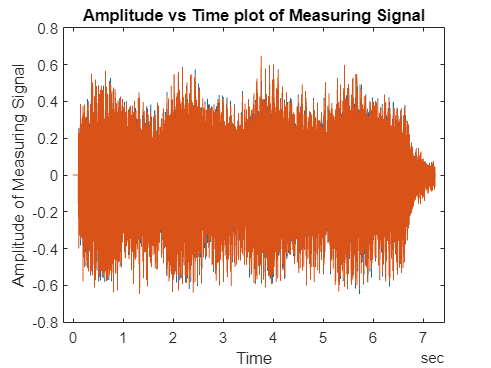

[y2,Fs2]= audioread(Signal);
t1 = 0:seconds(1/Fs2):seconds(info.Duration);
t1 = t1(1:end-1);
plot(t1,y2) 
title('Amplitude vs Time plot of Measuring Signal')
xlabel('Time') 
ylabel('Amplitude of Measuring Signal')

sound(y2,Fs2)


T=1/Fs2

T = 2.2676e-05

L = 72039;  
t = (0:L-1)*T; 
f2 = Fs2*(0:(L/2))/L;
P2 = abs(y2/L);
P1 = P2(1:L/2+1);

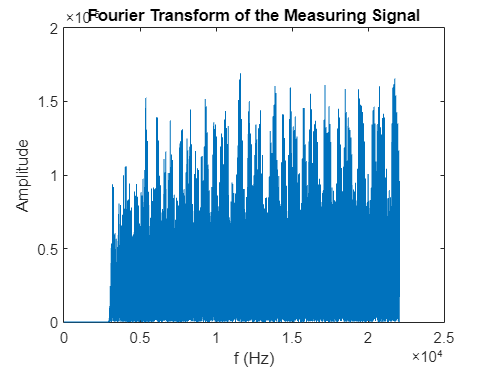

P1(2:end-1) = 2*P1(2:end-1);
plot(f2,P1) 
title('Fourier Transform of the Measuring Signal')
xlabel('f (Hz)')
ylabel('Amplitude')

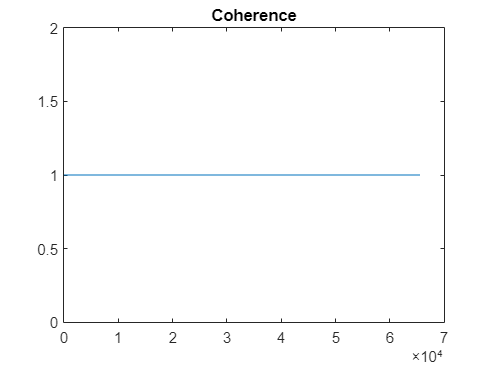



minLength = min(length(y1), length(y2));

y1 = y1(1:minLength);
y2 = y2(1:minLength);

cxy = mscohere(y1,y2);
confidence = max(cxy);


plot(cxy)
title('Coherence')

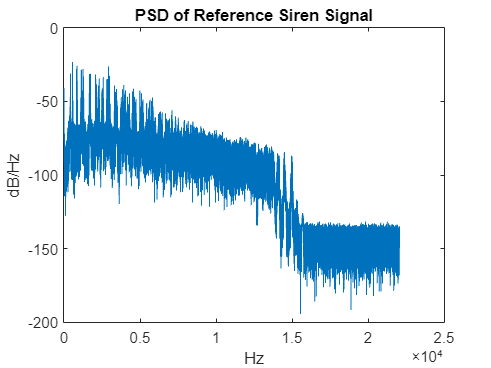

figure


psdestx = psd(spectrum.periodogram,y1,'Fs',Fs1,'NFFT',length(y1));
psdesty = psd(spectrum.periodogram,y2,'Fs',Fs2,'NFFT',length(y2));
plot(psdestx.Frequencies,10*log10(psdestx.Data));
title('PSD of Reference Siren Signal'); xlabel('Hz'); ylabel('dB/Hz');

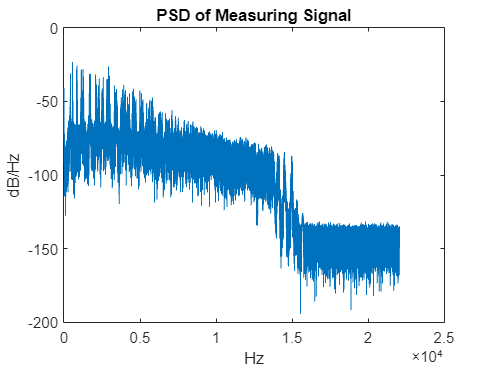

figure;
plot(psdesty.Frequencies,10*log10(psdesty.Data));
title('PSD of Measuring Signal'); xlabel('Hz'); ylabel('dB/Hz');




if (confidence >= 0.95)
    disp('Siren Sound is detected as sufficient confidence level is obtained') 

else 
    disp('There is not enough confidence level to ascertain the detection the Siren Sound.') 
end

Siren Sound is detected as sufficient confidence level is obtained
